# Create Path Following MPC Controller

In the previous examples you learned how to break a high level planning problem down into subproblems of global route planning, terrain-aware planning in free-space, and obstacle-aware local planning, but the issue of vehicle control was not addressed. In this example you will learn how to create a MPC-based controller for the purposes of following a reference-path, which can either be provided by one of the high-level global planners, or the local TEB planner highlighted previously.

Model Predictive Control is itself a deep topic, so this example will primarily focus on how to adapt the [`nlmpc`](https://www.mathworks.com/help/mpc/ref/nlmpc.html?s_tid=doc_ta) object to suit our purposes. For a deeper dive into the theory of MPC control, the [Getting Started with Model Predictive Control Toolbox](https://www.mathworks.com/help/mpc/getting-started-with-model-predictive-control-toolbox.html) provides background with accompanying tutorials. Put simply, MPC controllers require an estimated representation of a system's kinematics, used to linearize the system about a control point, and a cost function which tells an optimizer how to adjust control inputs to minimize some goal criteria that you want met. A key differentiator between MPC and a simple tuned PID controller is that MPC computes the optimal controls for a system given *online*, and MPC controllers often compute a *sequence* of control inputs which optimizes the system's response over some finite time horizon.

## Design Multistage Nonlinear MPC Tracking Controller

For this example, we will design a controller designed to run at `10hz`, with a control horizon of 1 second, giving us 10 control "stages" for our multi-stage non-linear MPC controller.

tsMPC = 0.1;
mpcHorizon = 1;
nStage = mpcHorizon/tsMPC;

## Create the NLMPC Object

One benefit of the `nlmpc` object is its ability to generalize to any plant and control model. We are controlling a 3DOF wheeled-vehicle, so for this example we will represent our system using a simple bicycle model, but with some minor tweaking this same object could be adapted to account for vehicle weight and surface terrain, or change the vehicle type entirely, e.g. a UAV or 6DOF car.

The state of our vehicle is $\left\lbrack x\;y\;\theta \;\right\rbrack$, and we control our vehicle using velocity and steering-angle $\left\lbrack v\;\alpha \;\right\rbrack$. This, alongside the stages we computed earlier, determines the size of the state and control space for the nlmpc object. Create the [`nlmpc`](docid:mpc_ref#mw_56547a96-970b-449a-929e-a3dadc671ab4) controller object with three states and two inputs.

mpcverbosity('off');
stateSize = 3;
controlSize = 2;
nlobjTracking = nlmpcMultistage(nStage,stateSize,controlSize);
nlobjTracking.Optimization.Solver = "fmincon";
nlobjTracking.Ts = tsMPC;

## Vehicle Parameters

To represent our vehicle, we leverage the vehicle-parameters defined for our TEB controller. Maintaining consistent values between the TEB and MPC subsystems will ensure that paths generated by our TEB planner can be followed (i.e. "reachable") by the downstream MPC controller.

The ego vehicle has two axles and four wheels. Define the ego vehicle parameters.

[tunableTEBParams,fixedTEBParams] = exampleHelperTEBParams

tunableTEBParams = struct with fields:
           LookaheadTime: 6
    ObstacleSafetyMargin: 1
             CostWeights: [1×1 struct]
        MinTurningRadius: 17.2000
             MaxVelocity: [16 0.9302]
         MaxAcceleration: [0.6000 0.1000]
      MaxReverseVelocity: 8


fixedTEBParams = struct with fields:
                Length: 6.5000
                 Width: 3
          NumIteration: 1
    ReferenceDeltaTime: 0.2000
      RobotInformation: [1×1 struct]


vWheelBase = fixedTEBParams.Length;

Specify the prediction model and its analytical Jacobian in the controller object. Since the model requires one parameters (`vWheelBase`), set `Model.ParameterLength` to 1.

nlobjTracking.Model.StateFcn        = "exampleHelperBicycleDerivative_MultiStage";
nlobjTracking.Model.StateJacFcn     = "exampleHelperBicycleJacobian_MultiStage";
nlobjTracking.Model.ParameterLength = 1;

Define constraints for the manipulated variables. Here, MV(1) is the ego vehicle speed in m/s, and MV(2) is the steering angle in radians.


$$-2 \text{m/s} \leq \text{Linear Velocity} \leq 2 \text{m/s}$$



$$-1.4 \text{m/s}^2 \leq \text{Linear Acceleration} \leq 3.33 \text{m/s}^2$$



$$-\frac{\pi}{6} \leq \text{Steering Angle} \leq \frac{\pi}{6}$$



$$$-0.5 \text{rad/s} \leq \text{Steering Angle Rate of Change} \leq 0.5 \text{rad/s} $$$


nlobjTracking.UseMVRate = true;
nlobjTracking.ManipulatedVariables(1).Min       = -tunableTEBParams.MaxReverseVelocity;
nlobjTracking.ManipulatedVariables(1).Max       =  tunableTEBParams.MaxVelocity(1);
nlobjTracking.ManipulatedVariables(1).RateMin   = -tunableTEBParams.MaxAcceleration(1);
nlobjTracking.ManipulatedVariables(1).RateMax   =  tunableTEBParams.MaxAcceleration(1);

vNom = nlobjTracking.ManipulatedVariables(1).Max;
ds = tsMPC*vNom;
nPt = 100;
refPath = linspace(0,ds*nPt,nPt+1)'.*[1 0 0];

% Set steer angle limits
nlobjTracking.ManipulatedVariables(2).Min       = -tunableTEBParams.MaxVelocity(2);
nlobjTracking.ManipulatedVariables(2).Max       =  tunableTEBParams.MaxVelocity(2);
nlobjTracking.ManipulatedVariables(2).RateMin   = -tunableTEBParams.MaxAcceleration(2);
nlobjTracking.ManipulatedVariables(2).RateMax   =  tunableTEBParams.MaxAcceleration(2);

Define cost function and gradient.

Cost function: $$
J = \sum_{k=1}^{p}  (x-x_{ref})'W_x(x-x_{ref}) + \sum_{k=1}^{p}  u'W_uu
$ $

for ct=1:nStage+1
    nlobjTracking.Stages(ct).CostFcn         = "exampleHelperBicycleCost_MultiStage";
    nlobjTracking.Stages(ct).CostJacFcn      = "exampleHelperBicycleGradient_MultiStage";
    nlobjTracking.Stages(ct).ParameterLength = 4;
end

Validate the controller design.

simdata = getSimulationData(nlobjTracking,'TerminalState');
simdata.StateFcnParameter = vWheelBase;
simdata.StageParameter = reshape([refPath(1:(nStage+1),:)'; repmat(nStage,1,nStage+1)],[],1);
validateFcns(nlobjTracking,[-14.8 0 0],[0.1 0],simdata);

Model.StateFcn is OK.
Model.StateJacFcn is OK.
"CostFcn" of the following stages [1 2 3 4 5 6 7 8 9 10 11] are OK.


"CostJacFcn" of the following stages [1 2 3 4 5 6 7 8 9 10 11] are OK.
Analysis of user-provided model, cost, and constraint functions complete.


## Extract MPC reference signal from reference path

Before we can use the MPC controller, we must clarify a few extra details on how the MPC controller works. At each timestep in the control horizon, the MPC controller attempts to minimize a cost function. For this example, the cost function [`exampleHelperBicycleCost_MultiStage`](matlab:open('./Helpers\MPCController\exampleHelperBicycleCost_MultiStage.m')) is comprised of 2 parts:


$$$
J = \sum_{k=1}^{p}  (x-x_{ref})'W_x(x-x_{ref}) + \sum_{k=1}^{p}  u'W_uu
$ $$


${\left(x-x_{\textrm{ref}} \right)}^{\prime } W_x \left(x-x_{\textrm{ref}} \right)$: Penalizes how far the current state is from a desired state at the current timestep (k)

${\dot{u} }^{\prime } W_u \dot{u}$: Penalizes the rate of change in control input for the current timestep (k)

The `nlmpc` object will provide us with $\dot{u}$, but we are responsible for providing the MPC controller with the desired reference states. We should assume that the upstream planners don't know anything about the downstream subsystems that will consume their reference path, so we need to add some logic to convert the reference path to an acceptable format. First, let us define an "optimal" control sequence as one that A) follows the path as quickly as permitted by our velocity constraints, and B) follows the path closely, since we are relying on the upstream planners to prevent collision and satisfy reachability requirements.

These two requirements lead us to the conclusion that an optimal set of reference states is equivalent to a sequence of SE2 states that are evenly spaced along the reference path, and whose spacing is determined by the timestep (`tsMPC`) and our optimal velocity (`vNom)`.

arclengthInterval = tsMPC*vNom;

We also want to ensure that we are following the reference path closely, and avoid cutting corners when transitioning from forward to reverse motion. Given these constraints, we develop the following helpers:

            [`exampleHelperFindPivots`](matlab:open('Helpers\MPCController\exampleHelperFindPivots.m'))`: `Identifies indices where a provided SE2 path changes direction

            [`exampleHelperEvenlyInterpSegment`](matlab:open('\Helpers\MPCController\exampleHelperEvenlyInterpSegment.m')): Fits a piece-wise semi-continuous set of arcs along a reference path and samples new states at even arclengths

            [`exampleHelperGenerateMPCReferenceSegment`](matlab:open('\Helpers\MPCController\exampleHelperGenerateMPCReferenceSegment.m')): Finds the closest point in a path to input state, selects the next `nStage+1` states, appends MPC params and reshapes as a vector for the MPC controller

#### <TODO> Show a simple example of this working on a basic set of SE2 states </TODO>

## Follow Road Network with MPC

You have assembled all of the pieces, now we should put them together.

#### Prepare simulation inputs

Start by loading a reference path generated by the route planner in example 1, and prepare the visuals for our simulation:

exampleHelperCreateBehaviorModelInputs

f = figure(1);
f.Visible="on";
cla;
binMap = binaryOccupancyMap(worldMat);
binMap.show;
hold on; axis equal;
teb.ReferencePath = smoothedReferencePath;
curPose = teb.ReferencePath(1,:);
curVel = [0 0];
prevVel = [0 0];
curIdx = 1;
nPts = 50;
hGlobalPath = exampleHelperPlotLines(smoothedReferencePath,'k-');
hLocalPath = exampleHelperPlotLines(curPose,'r-');
hPivot = exampleHelperPlotLines(curPose,'mO');
hMPCRef = exampleHelperPose2Quiver(curPose,{'Color','b'},ArrowSize=0.1);
hMPCSoln = exampleHelperPose2Quiver(curPose,{'Color','g','LineWidth',2},ArrowSize=0.2);
fUpdateQuiv = @(f,poses)set(f,'XData',poses(:,1),'YData',poses(:,2),'UData',cos(poses(:,3)),'VData',sin(poses(:,3)));
legend({'globalPath','localRoad','pivotPoints','mpcRefPath','mpcSolution'})

% Reset MPC initial guess
simdata.InitialGuess = [];

#### Simulate

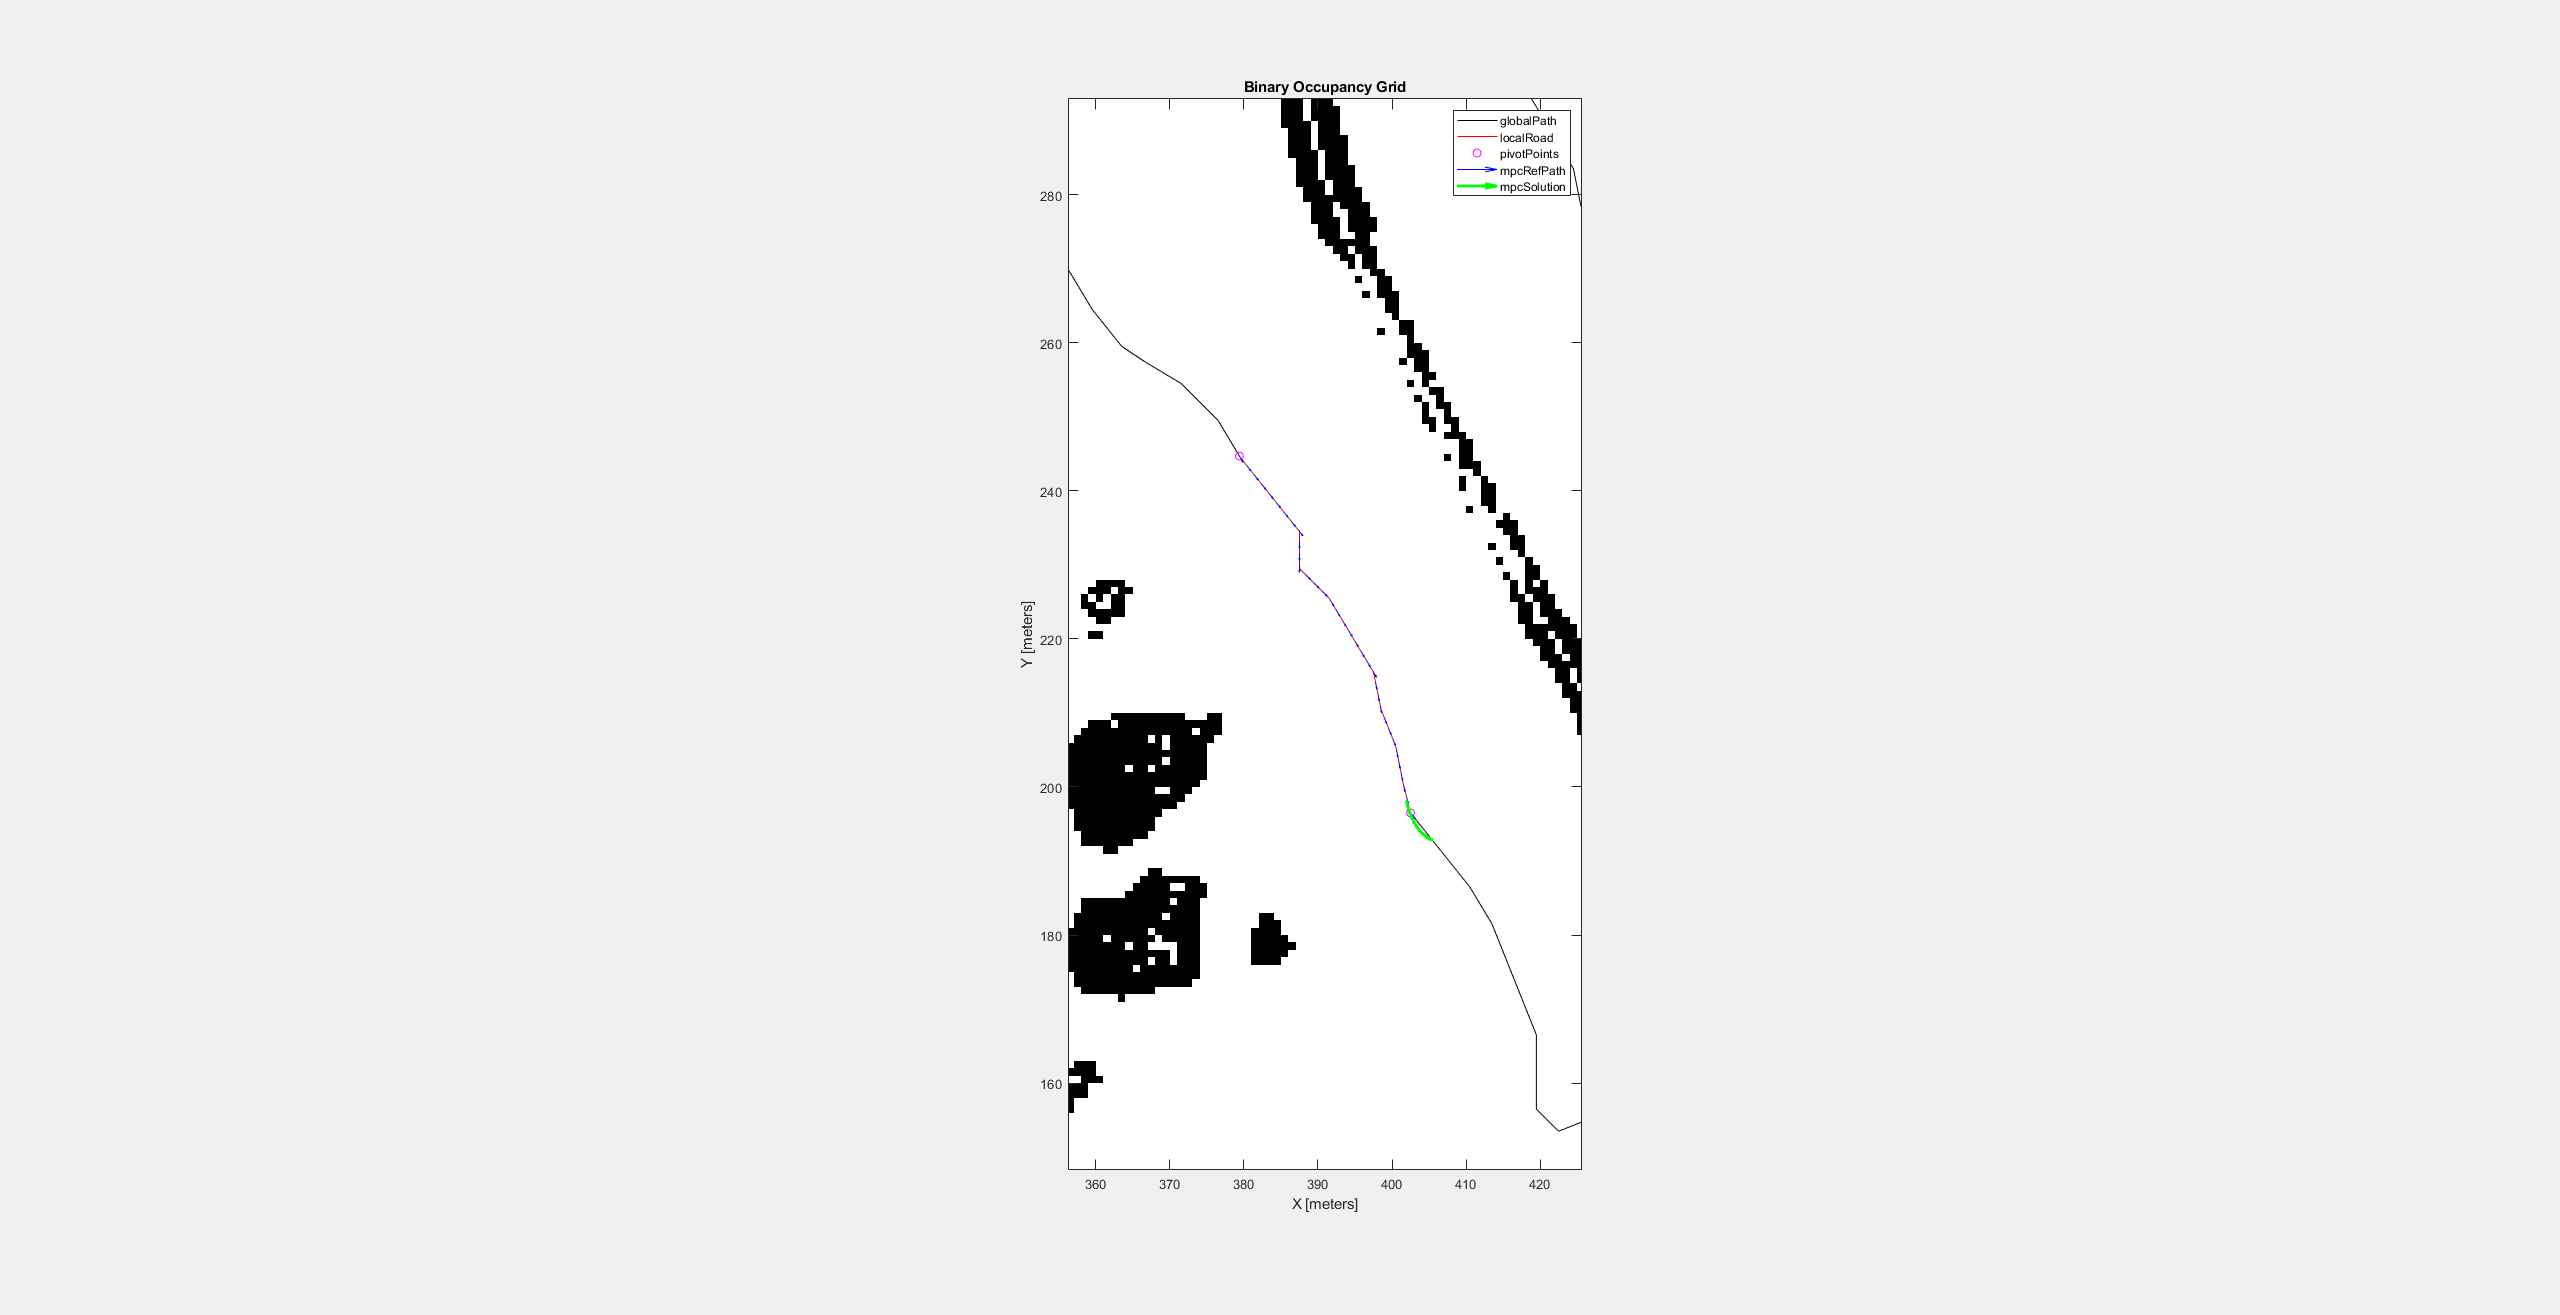


while vecnorm(curPose(1:2)-smoothedReferencePath(300,1:2),2,2) > 5
    
    % Generate segment list for next N points in smooth reference path
    initRefPath = smoothedReferencePath(curIdx:curIdx+nPts,:);
    [segmentList,pivotIdx,nSeg] = exampleHelperFindPivots(initRefPath);
    
    % Prep visualization
    set(hPivot,'XData',initRefPath(pivotIdx,1),'YData',initRefPath(pivotIdx,2));
    set(hLocalPath,'XData',initRefPath(:,1),'YData',initRefPath(:,2));
    exampleHelperPaddedZoom(initRefPath,2,"PaddingFactor",3);
    
    % Loop over & follow segments
    for iSeg = 1:nSeg
        segment = segmentList(iSeg).States;
        refPath = exampleHelperEvenlyInterpSegment(segment,vNom,nlobjTracking.Ts);
        fUpdateQuiv(hMPCRef,refPath); 
        while vecnorm(curPose(1:2) - segment(end,1:2),2,2) > 1
            % Generate reference states over prediction horizon
            simdata.StageParameter = exampleHelperGenerateMPCReferenceSegment(curPose,refPath,nlobjTracking.PredictionHorizon);
        
            % Step the controller
            [curVel,simdata,info] = nlmpcmove(nlobjTracking, curPose, prevVel, simdata);
            fUpdateQuiv(hMPCSoln,info.Xopt);
            drawnow limitrate;
    
            % Update state
            curPose = info.Xopt(2,:);
            prevVel = curVel;
        end
    end
    curIdx = min(curIdx+50,size(smoothedReferencePath,1));
end

## Follow Optimized TEB Paths with MPC

While running the simulation above, you may have noticed the MPC controller deviating from the reference path in certain spots, especially near sharp corners. While this didn't lead to problems in the current example, it is easy to imagine where this could go wrong if those sharp corners were located near obstacles. For this reason, we can leverage the local `controllerTEB` planner as an intermediary between the route planner and MPC controller. The TEB planner will produce collision-free results while adhering to our vehicle's simple bicycle model constraints, resulting in paths that the MPC controller is able to follow much easier.

#### Prepare TEB Planner

%% Setup TEB planner
% Load the digital elevation data generated in first example
load("OpenPitMinePart1Data.mat","dem","pathList");

% Load the reference path and planner parameters generated in second example
load("OpenPitMinePart2Data.mat","originalReferencePath","smoothedReferencePath","fixedTerrainAwareParams","tuneableTerrainAwareParams");

% Create costMaps from dem
[costMap,maxSlope] = exampleHelperDem2mapLayers(dem,tuneableTerrainAwareParams.MaxAngle,fixedTerrainAwareParams.Resolution);
obstacles = getLayer(costMap,"terrainObstacles");

% Generate TEB controller parameters
vehDims = exampleHelperVehicleGeometry(fixedTEBParams.Length,fixedTEBParams.Width,"collisionChecker");
collisionChecker = inflationCollisionChecker(vehDims,3);
exampleHelperInflateRoadNetwork(obstacles,pathList,collisionChecker.InflationRadius*1.5);

% Compute max distance traversible in an iteration of the local planner
maxDistance = (tunableTEBParams.MaxVelocity(1)*tunableTEBParams.LookaheadTime/obstacles.Resolution);

% Create the ego-centric local map
localMap = binaryOccupancyMap(2*maxDistance,2*maxDistance,obstacles.Resolution);
localMap.GridOriginInLocal = -localMap.GridSize/(2*localMap.Resolution);

% Construct planner
teb = controllerTEB(smoothedReferencePath, localMap);

% Update parameters
teb.NumIteration            = fixedTEBParams.NumIteration;
teb.ReferenceDeltaTime      = fixedTEBParams.ReferenceDeltaTime;
teb.RobotInformation        = fixedTEBParams.RobotInformation;
teb.ObstacleSafetyMargin    = tunableTEBParams.ObstacleSafetyMargin;
teb.LookAheadTime           = tunableTEBParams.LookaheadTime; % In seconds
teb.CostWeights.Time        = tunableTEBParams.CostWeights.Time;
teb.CostWeights.Smoothness  = tunableTEBParams.CostWeights.Smoothness;
teb.CostWeights.Obstacle    = tunableTEBParams.CostWeights.Obstacle;
teb.MinTurningRadius        = tunableTEBParams.MinTurningRadius;
teb.MaxVelocity             = tunableTEBParams.MaxVelocity;
teb.MaxAcceleration         = tunableTEBParams.MaxAcceleration;
teb.MaxReverseVelocity      = tunableTEBParams.MaxReverseVelocity;

#### Simulate

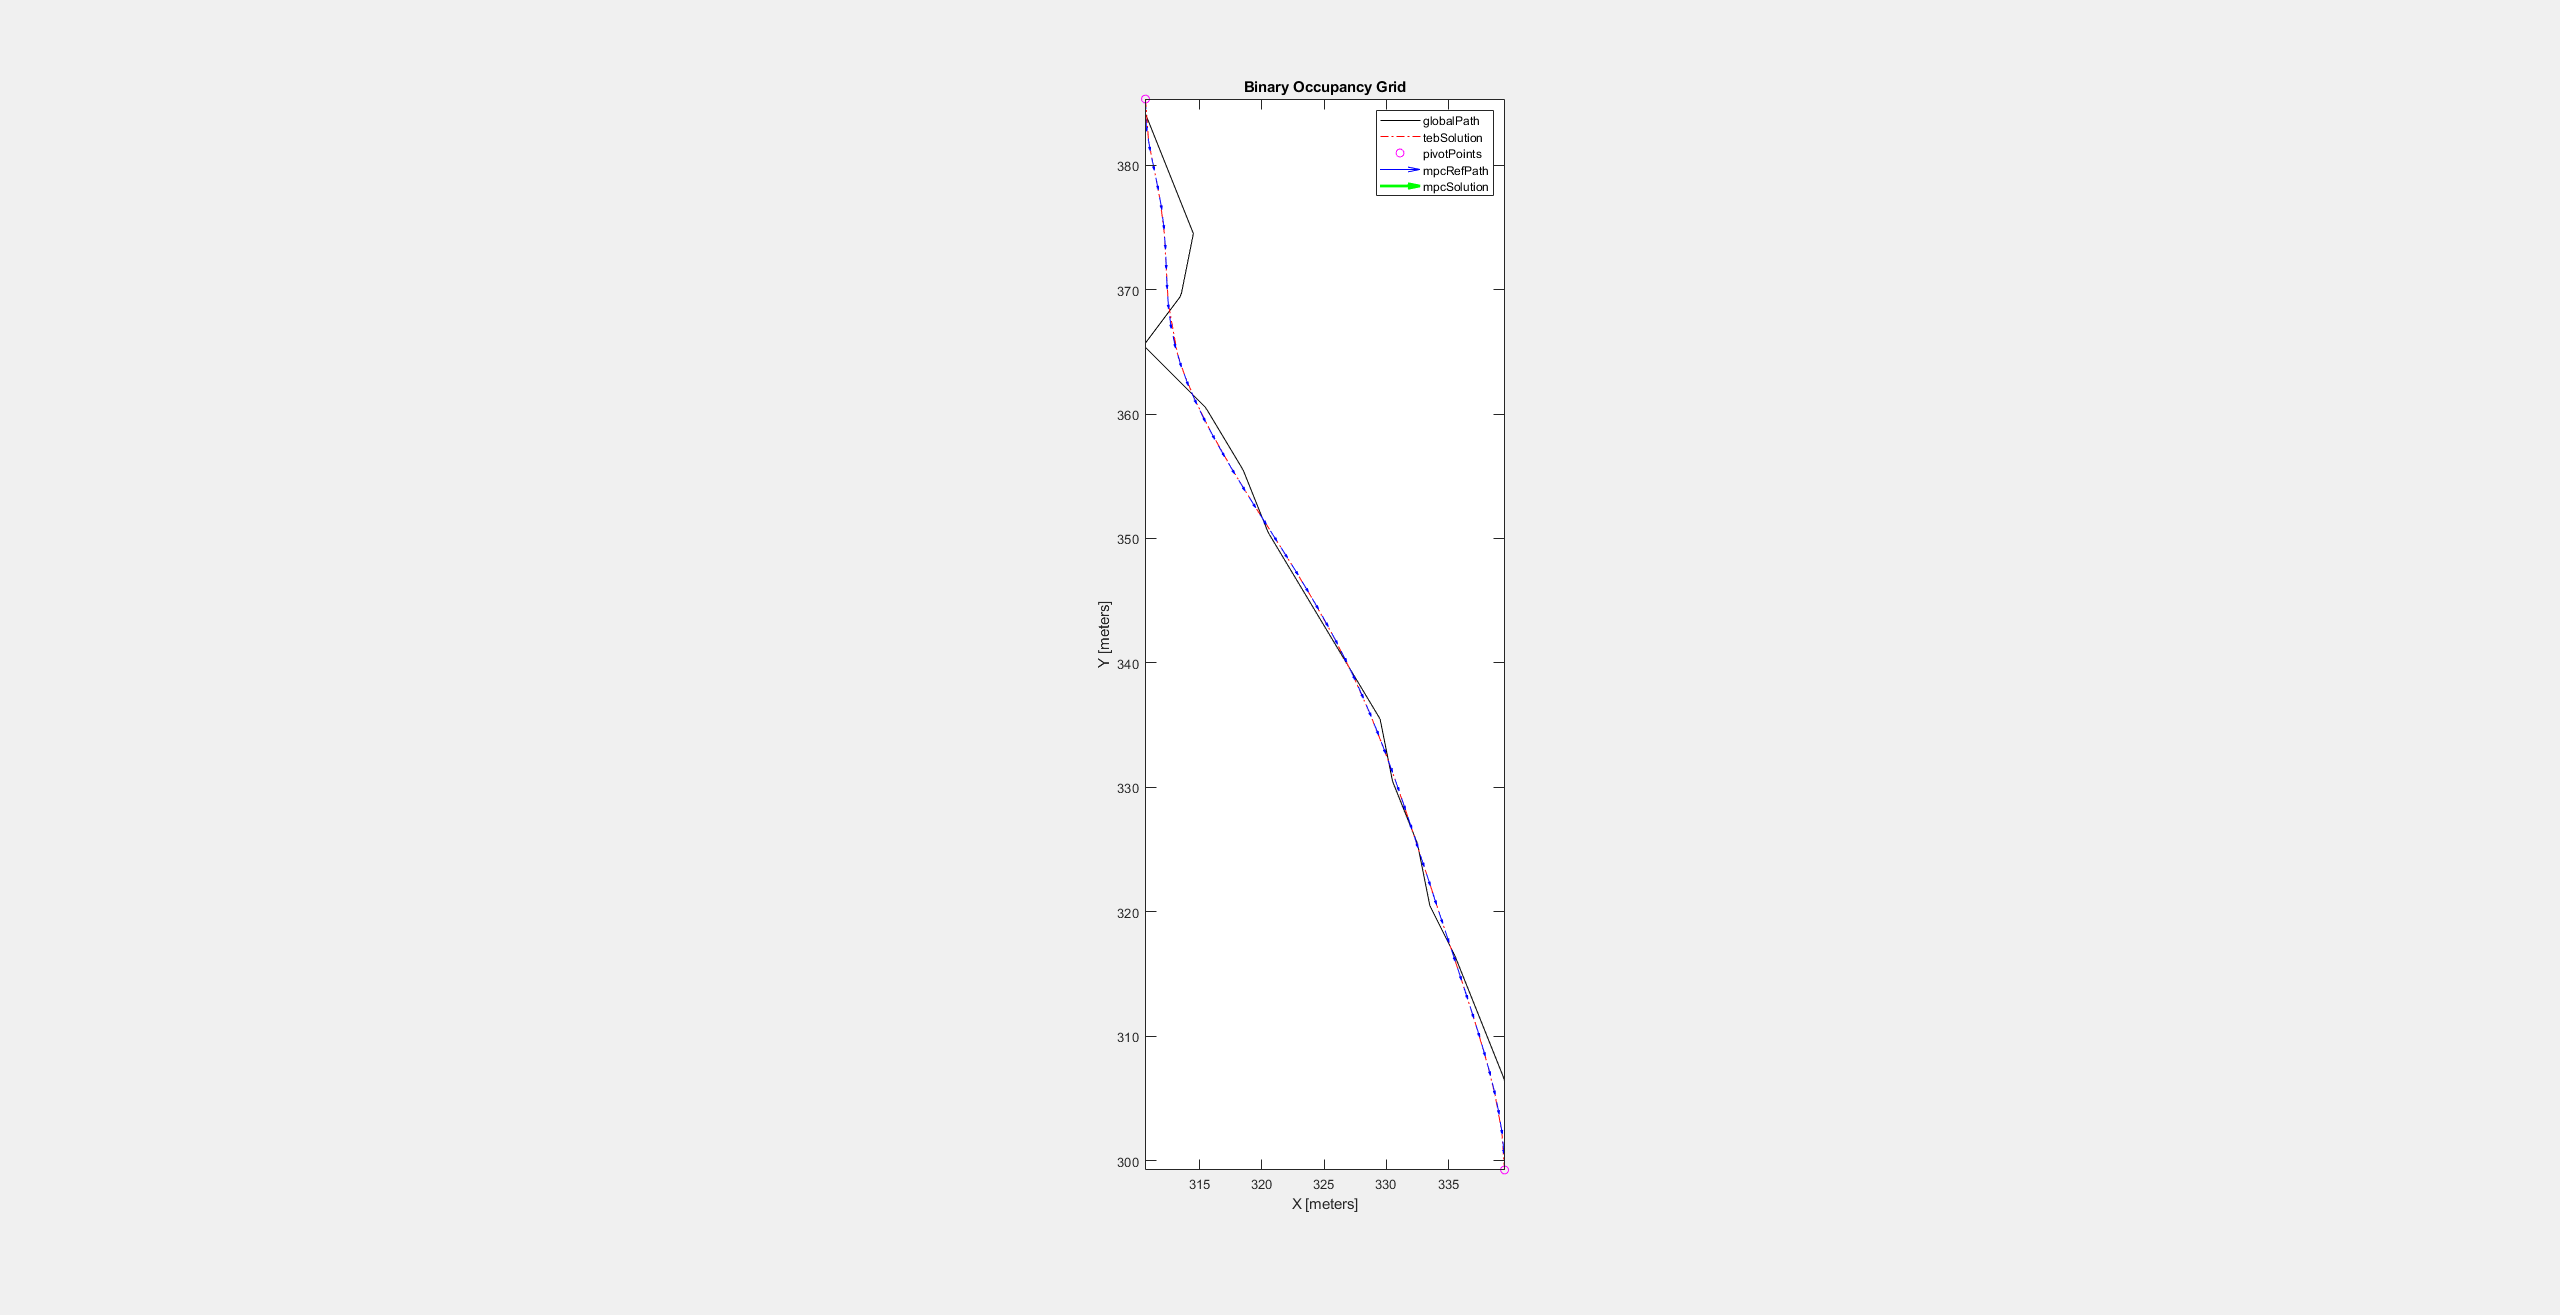

cla;
hold on; axis equal;
teb.ReferencePath = smoothedReferencePath;
curPose = teb.ReferencePath(1,:);
curVel = [0 0];
prevVel = [0 0];
adjustedPath = 0;
curIdx = 1;
localMap.move(curPose(1:2));
localMap.syncWith(obstacles);
localMap.show();
hGlobalPath = exampleHelperPlotLines(smoothedReferencePath,'k-');
hTEB = exampleHelperPlotLines(curPose,{'r-.',});
hPivot = exampleHelperPlotLines(curPose,'mO');
hMPCRef = exampleHelperPose2Quiver(curPose,{'Color','b'},ArrowSize=0.1);
hMPCSoln = exampleHelperPose2Quiver(curPose,{'Color','g','LineWidth',2},ArrowSize=0.2);
fUpdateQuiv = @(f,poses)set(f,'XData',poses(:,1),'YData',poses(:,2),'UData',cos(poses(:,3)),'VData',sin(poses(:,3)));
legend({'globalPath','tebSolution','pivotPoints','mpcRefPath','mpcSolution'})

% Reset MPC initial guess
simdata.InitialGuess = [];
while vecnorm(curPose(1:2)-smoothedReferencePath(200,1:2),2,2) > 20
    % Use controllerTEB to generate local optimal trajectory
    move(localMap,curPose(1:2),"MoveType","Absolute","SyncWith",obstacles);
    
    % Generate new vel commands with teb
    [velcmds,tstamps,curPath,info] = teb(curPose, curVel);
    
    if info.HasReachedGoal
        break;
    end

    hTEBPath2_2.Matrix(1:3,:) = [eul2rotm([0 0 curPose(3)],'XYZ') [curPose(1:2)';0]];
    
    % Post-process the TEB results, handling error codes and constraint
    % violations.
    [velcmds,tstamps,curPath,adjustedPath,needLocalReplan,needFreeSpaceReplan] = ...
        exampleHelperProcessTEBErrorCodes(teb,curPose,curVel,velcmds,tstamps,curPath,info,adjustedPath, ...
        teb.RobotInformation.Dimension(1),teb.RobotInformation.Dimension(2));

    if adjustedPath
        continue;
    end

    % Generate segment list for next N points in smooth reference path
    initRefPath = curPath(1:max(2,size(curPath,1)),:);
    [segmentList,pivotIdx,nSeg] = exampleHelperFindPivots(initRefPath);
    simdata.InitialGuess = zeros(nlobjTracking.PredictionHorizon*7+3,1);

    % Prep visualization
    set(hTEB,'XData',initRefPath(:,1),'YData',initRefPath(:,2));
    set(hPivot,'XData',initRefPath(pivotIdx,1),'YData',initRefPath(pivotIdx,2));
    
    % Loop over & follow segments
    for iSeg = 1:nSeg
        segment = segmentList(iSeg).States;
        [refPath,k] = exampleHelperEvenlyInterpSegment(segment,vNom,nlobjTracking.Ts,velcmds);
        
        fUpdateQuiv(hMPCRef,refPath);
        while vecnorm(curPose(1:2) - segment(end,1:2),2,2) > 0.4
            % Generate reference states over prediction horizon
            [mpcRef,idx] = exampleHelperGenerateMPCReferenceSegment(curPose,refPath,nlobjTracking.PredictionHorizon);
            simdata.StageParameter = mpcRef;
        
            % Step the controller
            [curVel,simdata,info] = nlmpcmove(nlobjTracking, curPose, prevVel, simdata);
            fUpdateQuiv(hMPCSoln,info.Xopt);
    
            % Update state
            curPose = info.Xopt(2,:);
            prevVel = curVel;
            localMap.show(FastUpdate=1);
            exampleHelperPaddedZoom(initRefPath,2,"PaddingFactor",1);
            drawnow;
        end
    end
    curIdx = min(curIdx+50,size(smoothedReferencePath,1));
end

## Conclusion

In this example you learned how to construct a model predictive controller for a simple 3DOF vehicle. You learned how to configure an nlmpc object for the 3DOF plant, and how to design state-update and cost-functions such that our vehicle can follow a reference path. You also learned how to design a simple reference signal such that the vehicle can optimally move along a reference path. Lastly, you saw how this controller can be designed to work with different upstream subsystems, such as a simple route-planner, or controllerTEB.

In the last example, [`ModelAndControlAutonomousHaulTruck`](matlab:open('ModelAndControlAutonomousHaulTruck')), you will see how the same system can be modeled in Simulink.